# Bed load transport time series analysis 

This script analyzes the output obtained by running the code *main_bedload.m.*  

load timeSeries.mat % Tables with data computed from the text file

## Bed load cumulative sum: Linear Fit 

One of the simplest ways to detect if a time series corresponds to a stationary process is to perform a linear fit. The slope of the resulting equation gives the mean rate of change of the time series. In our case it should give the bed load transport rate:

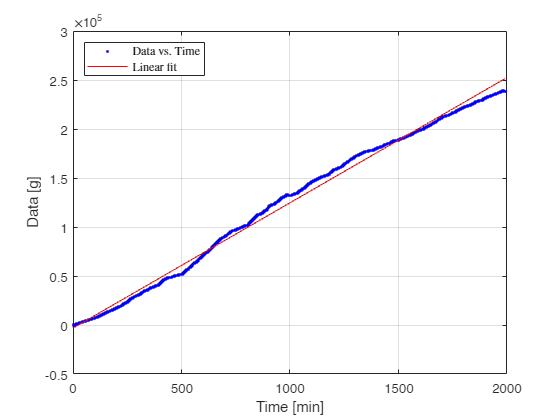

tim = time2num(allAggTable.dt);
serie = allAggTable.GlobalCumBedload;
[fitresult, gof] = createLinearFit(tim, serie);

We remember that the linear model has the form: f(x) = p1*x + p2. In our case, these values are:

p1 = fitresult.p1

p1 = 127.8565

p2 = fitresult.p2

p2 = -3.1283e+03

## Instantaneous bed load rate stationarity

In this section we analyze the instantaneous values for bed load transport rate:

instBL = allAggTable.PositiveBedloadRate;

We plot it to see it:

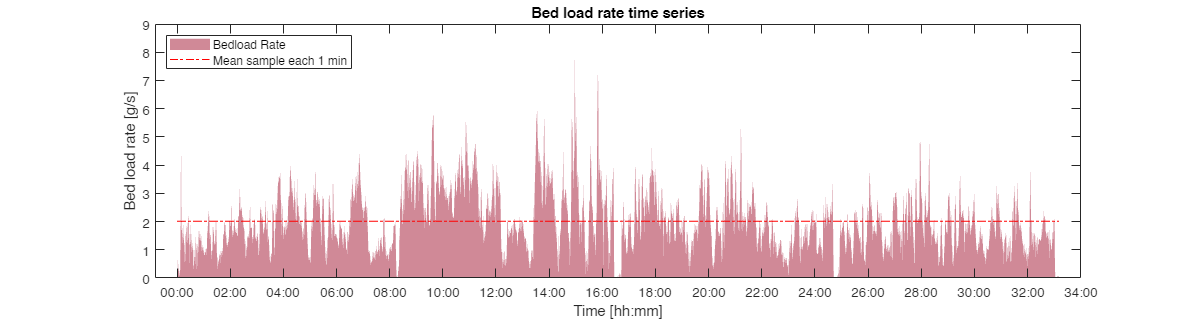

figure('Position', [10 10 1500 400])
area(allAggTable.dt, instBL,"FaceColor", "#A2142F","FaceAlpha",0.5,"EdgeColor","none",DisplayName="Bedload Rate")
hold on 
plot(allAggTable.dt, ones(height(allAggTable),1)*mean(allAggTable.PositiveBedloadRate),'r-.', DisplayName='Mean sample each 1 min')
title("Bed load rate time series")
legend(Location="northwest")
xtickformat("hh:mm")
xlabel("Time [hh:mm]")
ylabel("Bed load rate [g/s]")

### Augmented Dickey-Fuller (ADF) test

[hADF, pValueADF, statADF] = ADFtest(instBL)

ADF test statistic: -5.9366
p-value: 0.001
The time series is stationary


hADF = logical
   1


pValueADF = 1.0000e-03

statADF = -5.9366

### Kwiatkowski-Phillips-Schmidt-Shin (KPSS) test

[hKPSS, pValueKPSS, statKPSS] = KPSStest(instBL)

KPSS test statistic: 5.1442
p-value: 0.01
The time series is non-stationary


hKPSS = logical
   1


pValueKPSS = 0.0100

statKPSS = 5.1442

### Phillips-Perron (PP) test

[h, pValue, stat] =  PPtest(instBL)

PP test statistic: -5.9366
p-value: 0.001
The time series is non-stationary


h = logical
   1


pValue = 1.0000e-03

stat = -5.9366